# Lab2

## Objectives

### Model identification

- Parameter estimation

- Calibration & validation

Empirical model for reservoir inflows

- Linear AR model

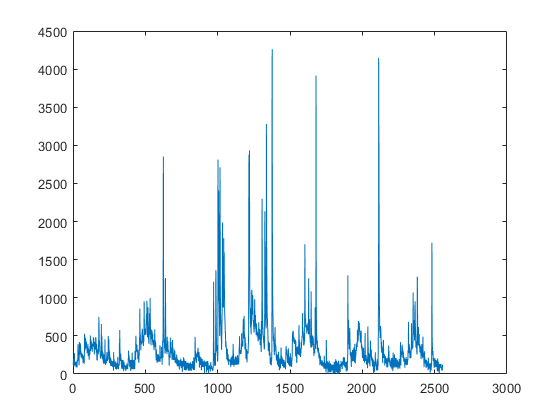

addpath('utils\');
% Exercise 1 - Stationary statistics
data = load("data\Verbano_inflows_74_83_nb.txt");
T = 365;
train_years = 7;
training_data = data(1:train_years*T);
validation_data = data(train_years*T + 1:end);
% plot(data(:,2),data(:,1), '*')
plot(training_data)

N = length(training_data)

N = 2555

data_min = min(training_data)

data_min = 1.5000

data_max = max(training_data)

data_max = 4.2614e+03

data_range = range(training_data)

data_range = 4.2599e+03

data_mean = mean(training_data)

data_mean = 323.7360

data_var = var(training_data)

data_var = 1.1570e+05

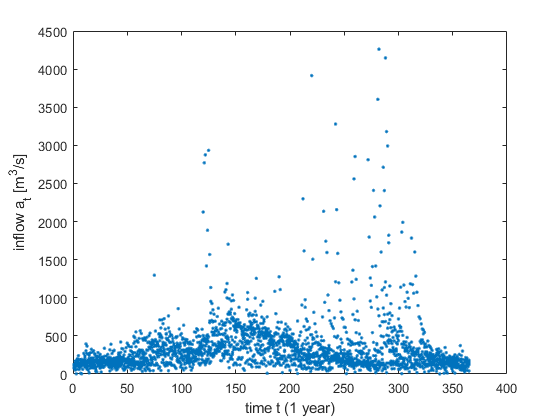

% Exercise 2 - Cyclostationary statistics

% Periodicity
tt = repmat([1:T]', N/T, 1);
figure;
plot(tt ,training_data ,'.' );
xlabel('time t (1 year)'); 
ylabel('inflow a_t [m^3/s]');

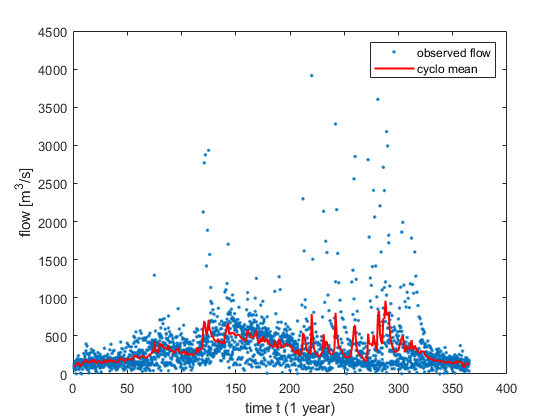

Q = reshape(training_data, T, train_years);
% Cyclo-stationary mean
Cm = mean(Q,2); % Same as mean(Q')'
% Cyclo-stationary variance
Cv = var(Q')';
plot(tt, training_data, '.' );
hold on;
plot(Cm, 'r', 'LineWidth', 1.5); 
legend('observed flow', 'cyclo mean');
xlabel('time t (1 year)');
ylabel('flow [m^3/s]');

% Exercise 3 - Cyclostationary moving variance
T = 365;
f = 5;
% Moving Average
[mi, m] = moving_average(training_data, T, f);
% Moving variance
[ma_var2, s2] = moving_average((training_data - m).^2, T, f);
ma_var = ma_var2.^(1/2);
s = s2.^(1/2);

N = length(training_data);
cyc_mse = mse_performance(training_data,m)

cyc_mse = 9.8108e+04

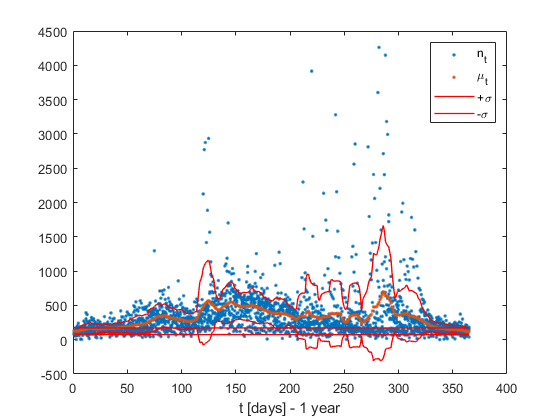

figure;
plot(tt, [training_data, m], '.');
xlabel('t [days] - 1 year');
hold on;
plot(tt, m + s, 'r', 'LineWidth',1);
plot(tt, m - s, 'r', 'LineWidth',1);
legend('n_t', '\mu_t', '+\sigma', '-\sigma');

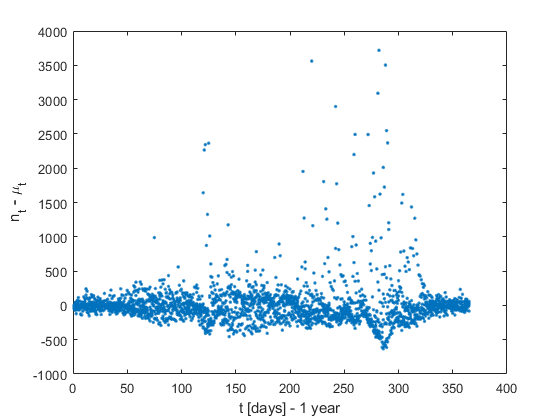

figure;
plot(tt, training_data - m, '.')
xlabel('t [days] - 1 year');
ylabel('n_t - \mu_t');

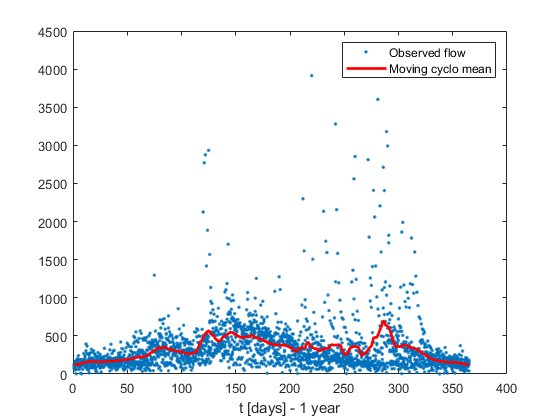

figure;
plot(tt, training_data, '.');
hold on;
plot([1 : T], mi, 'r', 'LineWidth',2);
legend('Observed flow', 'Moving cyclo mean');
xlabel('t [days] - 1 year');

% Exercise 4 - Param identification, linear model
data2 = load("data\storage_surface.txt");

y = data2(:,1);
x = data2(:,2);
N = length(x);

M = ones(size(data2));
M(:,1) = x;

theta = M\y;
a = theta(1);
b = theta(2);
lin_reg = a*x + b;

% Homework - Approximate power law model
% TODO: Check power law param estimation

lin_mse = mse_performance(y,lin_reg)

lin_mse = 8.7707e+10

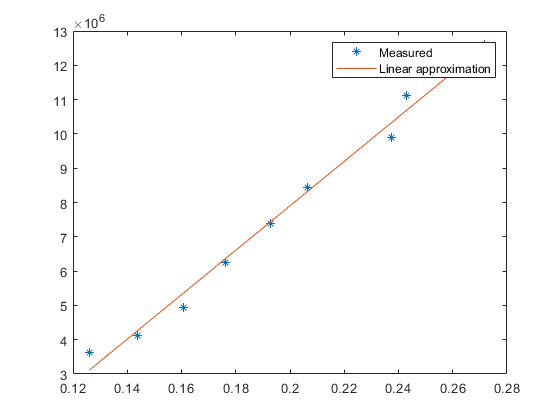

figure;
plot(x, y,'*');
hold on;
plot(x, lin_reg);
legend('Measured', 'Linear approximation');

### Exercise 5 - AR(1) estimation

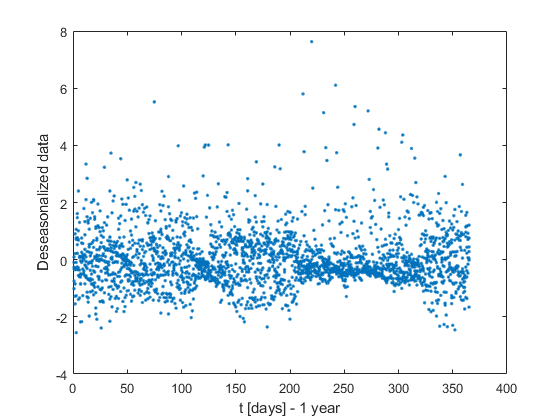

% Deseasonalize
x = (training_data - m) ./ s;

figure; 
plot(tt, x, '.');
xlabel('t [days] - 1 year');
ylabel('Deseasonalized data');

% Param estimation - 1-step ahead
% RECALL MIDA: Pseudo-inverse
y = x(2:end);
M = x(1:end-1);
theta = M\y

theta = 0.7386

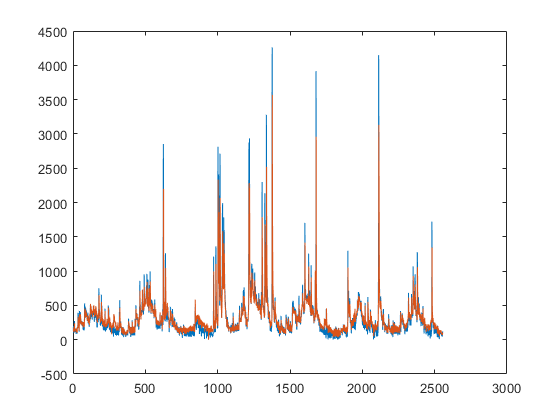

data_ar1 = M * theta;
data_ar1 = [x(1); data_ar1];

% Seasonalized regressor
data_ar1_reg = data_ar1 .* s + m;

figure; plot([training_data, data_ar1_reg]);

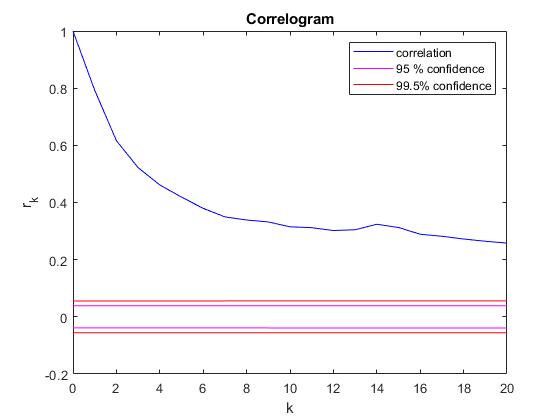

figure;
correlogram(training_data, training_data, 20);
xlabel('k');
ylabel('r_k');

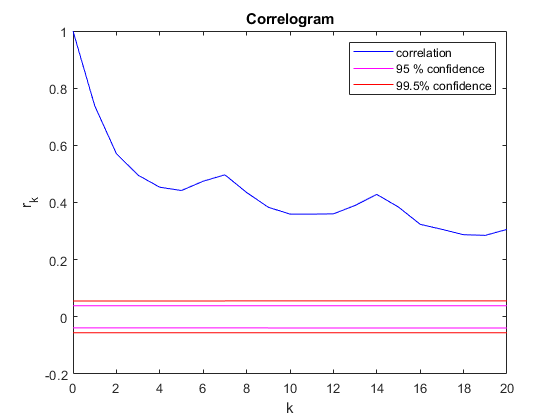

figure;
correlogram(x, x, 20);
xlabel('k');
ylabel('r_k');

#### Performance of AR(1)

- Checking error correlation: Whiteness test

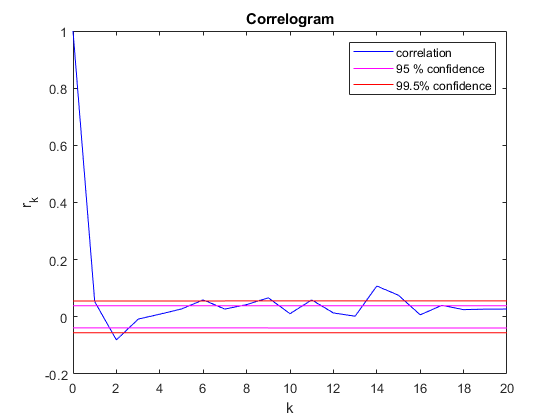

error = training_data - data_ar1_reg;

figure;
correlogram(error, error, 20);
xlabel('k');
ylabel('r_k');

2. Synthetic performance index - MSE

ar1_mse = mse_performance(training_data, data_ar1_reg)

ar1_mse = 4.2217e+04

3. Synthetic performance index - R

ar1_r2 = r2_performance(training_data, data_ar1_reg, m)

ar1_r2 = 0.5697

#### Validation

% Moving Average
[mi_val, m_val] = moving_average(validation_data, T, 5);
% Moving variance
[ma_var2_val, s2_val] = moving_average((validation_data - m_val).^2, T, 5);
s_val = s2_val .^(1/2);
% Deseasonalized validation dataset
x_val = (validation_data - m_val) ./ s_val;


M_ar1_val = x_val(1: end-1);
val_ar1 = M_ar1_val * theta;
val_ar1 = [x_val(1); val_ar1];
val_ar1_reg = val_ar1 .* s_val + m_val;
r2_performance(validation_data, val_ar1_reg, m_val)

ans = 0.3293

### Exercise 6 - AR(2)

y = x(3:end);
M_ar2 = [x(2:end-1), x(1:end-2)];
theta = M_ar2\y;
data_ar2 = M_ar2*theta;
data_ar2 = [x(1:2); data_ar2];
data_ar2_reg = data_ar2 .* s + m;
ar2_mse = mse_performance(training_data, data_ar2_reg)

ar2_mse = 4.2593e+04

ar2_r2 = r2_performance(training_data, data_ar2_reg, m)

ar2_r2 = 0.5659

#### Validation

M_ar2_val = [x_val(2:end-1), x_val(1:end-2)];
val_ar2 = M_ar2_val * theta;
val_ar2 = [x_val(1:2); val_ar2];
val_ar2_reg = val_ar2 .* s_val + m_val;
r2_performance(validation_data, val_ar2_reg, m_val)

ans = 0.3264

### Exercise 7 - AR(3)

y = x(4:end);
M_ar3 = [x(3:end-1), x(2:end-2), x(1:end-3)];
theta = M_ar3\y

theta =     0.6904
   -0.0304
    0.1235


data_ar3 = M_ar3*theta;
data_ar3 = [x(1:3); data_ar3];
data_ar3_reg = data_ar3 .* s + m;
ar2_mse = mse_performance(training_data, data_ar2_reg)

ar2_mse = 4.2593e+04

ar2_r2 = r2_performance(training_data, data_ar2_reg, m)

ar2_r2 = 0.5659

#### Validation

M_ar3_val = [x_val(3:end-1) x_val(2:end-2), x_val(1:end-3)];
val_ar3 = M_ar3_val * theta;
val_ar3= [x_val(1:3); val_ar3];
val_ar3_reg = val_ar3 .* s_val + m_val;
r2_performance(validation_data, val_ar2_reg, m_val)

ans = 0.3264